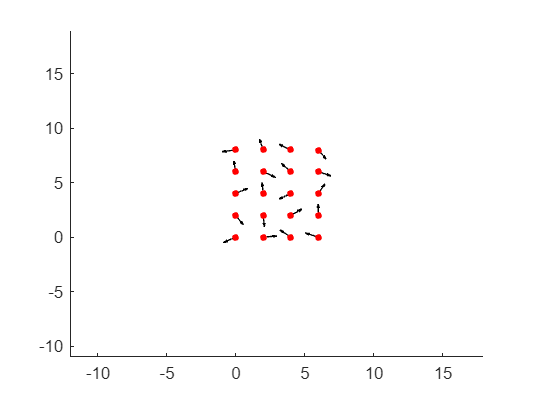

horizon = 5000; % time horizon of the simuation
dt = 0.01; % delta time
t = 0;
collided = false;

% Set up the figure and axis
% figure('Position', [100 100 800 600]);
limit = 50;
min_d = 2;

% Initialize the boids
num_boids = 20;
phase = 1;
transition_idx = 0;

[q, p] = generate_boids(num_boids, limit, min_d);

% % actuation is modelled using a first-order approxomation
% % time delays in [desired] actuation: acceler bbbbbbbbbbbbbbbbbbbbbbbbbbbbbbbbbbbnn ation, bank angle
% tau_a = 0.1;
% tau_phi = 0.1;

max_vel = 1;
min_vel = 1;
max_accel = 10;
num_collisions = 0;

accelerations = zeros(num_boids, 1);
bank_angles = zeros(num_boids, 1);

collisions = zeros(horizon, 1); % collisions occuring at all timesteps
max_distances = zeros(horizon, 1); % maximum distance between two neighbours
average_distances = zeros(horizon, 1); % average --
min_distances = zeros(horizon, 1); % minimum --
H_p = zeros(horizon, 1); % energy function - ||p|| squared
H_v = zeros(horizon, 1); % energy function - ||v|| squared

forces = zeros(horizon, 2); % mainly useful in two agent testing
positions = zeros(horizon, 2);
velocities = zeros(horizon, 2);
gammas = zeros(horizon, 1);
angle_deviations = zeros(horizon, 1);

% System Params
epsilon = 1;
d = 0.07*10;
kappa = 9.8/7;
r = kappa*d;
h = 0.2;
phi_max = 45;
g = 9.8;
omega_max = (g * tand(phi_max)) / max_vel;

% A lower bound on inter-agent distance, beyond which we consider a collision
d_th = 0.1;

sys_params = [epsilon, d, kappa, h, max_accel, ...
    phi_max, g, t, phase, transition_idx];

% Update Loop
hold on;
for i = 1:horizon
    t = i / 100;
    neighbours = findNeighbours(q, q, r);
    sys_params(11) = t;

    target_accelerations = zeros(num_boids, 1);
    target_omegas = zeros(num_boids, 1);
    f = zeros(num_boids, 2);

    % Main loop to calculate forces on each boid
    for j = 1:num_boids
        neighbours_of_j = neighbours{j};
        force_on_j = generate_force(q, p, j, sys_params, false);
        target_accelerations(j) = force_on_j(1);
        target_omegas(j) = force_on_j(2);
    end

    % Get adjacency matrices and compute laplacian
    g = get_weighted_adjacency_matrix(q, r);
    A = bump(g, h);
    G = graph(g);
    L = laplacian(G);
    comp_numbers = conncomp(graph(L));
    unique_ids = unique(comp_numbers);

    % Calculate group forces
    q_groups = zeros(numel(unique_ids), 2);
    p_groups = zeros(numel(unique_ids), 2);
    f_k = zeros(numel(unique_ids), 2);

    for j = 1:numel(unique_ids)
        q_groups(j,:) = mean(q(comp_numbers == unique_ids(j),:), 1);
        p_groups(j,:) = mean(p(comp_numbers == unique_ids(j),:), 1);
    end

    for j = 1:numel(unique_ids)
        f_k(j,:) = generate_force(q_groups, p_groups, j, sys_params, true);
    end

    % Update accelerations and omegas with group forces
    for k = 1:num_boids
        f_k_idx = comp_numbers(k);
        target_accelerations(k) = 0.8 * target_accelerations(k) + 0.2 * f_k(f_k_idx,1);
        target_omegas(k) = 0.8 * target_omegas(k) + 0.2 * f_k(f_k_idx,2);
    end

    clip(target_accelerations, -max_accel, max_accel);
    clip(target_omegas, -omega_max, omega_max);

    % Update velocity and position for each boid
    for j = 1:num_boids
        speed = vecnorm(p(j,:), 2);
        force_on_j = [target_accelerations(j), target_omegas(j)];
        p(j,:) = force_on_j(1) * (p(j,:) / speed) * dt + p(j,:);
        dtheta = force_on_j(2) * dt;
        p(j,:) = ([cos(dtheta), sin(dtheta); -sin(dtheta), cos(dtheta)] * p(j,:)')';

        % Clip the velocity
        p(j, :) = p(j, :) / speed * clip(speed, min_vel, max_vel);
        q(j,:) = q(j,:) + p(j,:) * dt;
    end

    % Inter-agent distance calculations
    max_distance = max(g, [], 'all');
    min_distance = min(g(g > 0), [], 'all');
    average_distance = mean(g(g > 0), "all");

    max_distances(i) = max_distance;
    if isempty(min_distance)
        min_distances(i) = 0;
    else
        min_distances(i) = min_distance;
    end
    average_distances(i) = average_distance;

    % Calculate "Energy Terms"
    for j = 1:num_boids
        for k = j+1:num_boids
            angle_deviations(i) = angle_deviations(i) + angle(p(j,:), p(k,:))^2;
            distance_jk = vecnorm(q(j,:)-q(k,:),2,2);
            d_alpha = sigmanorm(d, epsilon);
            r_alpha = sigmanorm(r, epsilon);
            V = psi_alpha(distance_jk, @phi_alpha, d, 8, 10, epsilon, h, d, r);
            H_p(i) = H_p(i) + V;
            H_v(i) = H_v(i) + V;
        end
    end

    H_p(i) = H_p(i) + 1/2 * sum(p.^2, 'all');
    v = p - mean(p,1);
    H_v(i) = H_v(i) + 1/2 * sum(v.^2, 'all');

    % Handle phase transitions
    if phase == 1 && angle_deviations(i) < 0.1
        phase_change_index1 = i;
        phase = 2;
        max_vel = 5;
        transition_idx = 0;
        sys_params(9) = phase;
    end

    if phase == 2 && transition_idx <= 1
        transition_idx = transition_idx + 0.01;
        sys_params(10) = transition_idx;
    end

    if transition_idx >= 1 && phase == 2
        phase_change_index2 = i;
        phase = 3;
        sys_params(9) = phase;
    end

    % Check for collisions
    collisions(i) = check_collisions(q, d_th);
    num_collisions = num_collisions + collisions(i);
    if num_collisions > 0
        collided = true;
        break;
    end

    % Plotting the current state
    cla;
    s = sparse(g);
    xm = mean(q(:,1));
    ym = mean(q(:,2));
    window = 15;
    xlim([xm - window, xm + window]);
    ylim([ym - window, ym + window]);
    scalex = 2 * window / 30;
    scaley = 2 * window / 30;

    gplot(s, q);
    quiver(q(:,1), q(:,2), scalex * (p(:,1) ./ vecnorm(p,2,2)), scaley * (p(:,2) ./ vecnorm(p,2,2)), 0, 'k');
    plot(q(:,1), q(:,2), 'ro', 'MarkerSize', 3.5, 'MarkerFaceColor', 'red');
    pause(0.01);
end

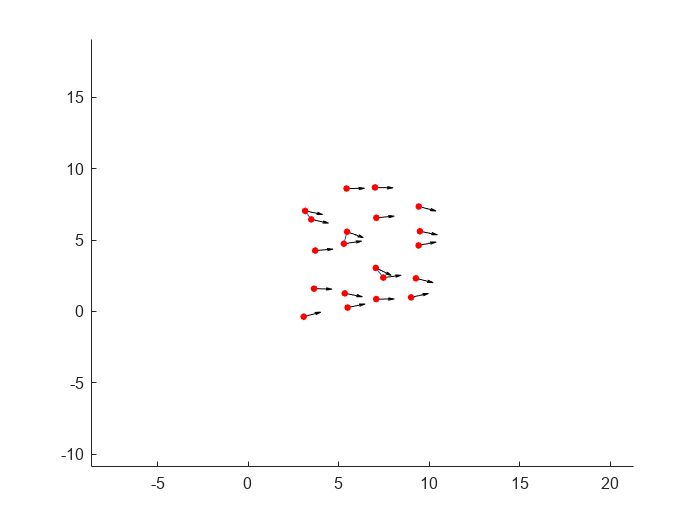

hold off;

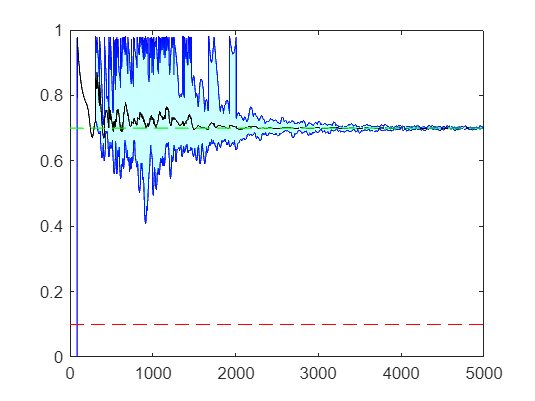

% vecnorm(p, 2, 2)
% % 
% % plot(collisions);
% % title("Collisions");
% % plot_name = "Collisions.png";
% % % exportgraphics(gca, plot_name);
% % % 
a1 = plot(max_distances, 'b-');
hold on;
plot(min_distances, 'b-');
% % Fill the area between the lines
x_values = 1:numel(max_distances);
fill([x_values fliplr(x_values)], [max_distances' fliplr(min_distances')], 'c', 'EdgeColor', 'none', 'FaceAlpha', 0.2);
a2 = plot(average_distances, 'k-');
a3 = plot([0, horizon], [d, d], 'g--');
a4 = plot([0, horizon], [d_th, d_th], 'r--');
% % xline([phase_change_index1, phase_change_index2], 'k-.');
hold off;

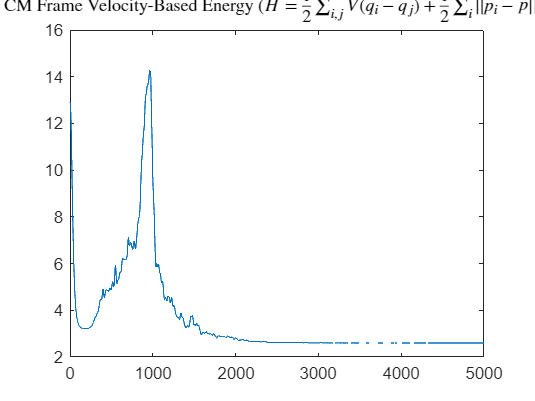

% % legend([a1, a2, a3, a4], {'Maximum/Minimum', 'Average',  'Desired', 'Collision Boundary'})
% title("Inter-Agent Distances (Only Neighbours)");
% plot_name = "plots/Interagent_distances.png";
% % % exportgraphics(gca, plot_name);
% % 
plot(H_v);
title("CM Frame Velocity-Based Energy ($H = \frac{1}{2}\sum_{i,j}V(q_i - q_j) + \frac{1}{2}\sum_i||p_i-\bar{p}||^2$)", Interpreter="latex");

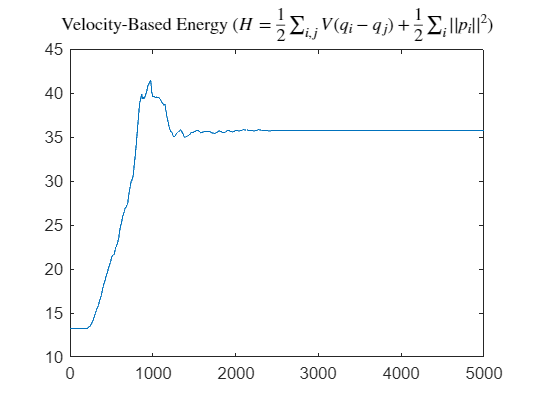

% % plot_name = "H_v.png";
% % exportgraphics(gca, plot_name);
% % 
plot(H_p);
title("Velocity-Based Energy ($H = \frac{1}{2}\sum_{i,j}V(q_i - q_j) + \frac{1}{2}\sum_i||p_i||^2$)", Interpreter="latex");

% % plot_name = "H_p.png";
% exportgraphics(gca, plot_name);

% x = (1:phase_change_index1)';
% f = fit(x, angle_deviations(1:phase_change_index1), 'exp1');
% plot(angle_deviations(1:phase_change_index1), '-', 'LineWidth', 1);
% hold on;
% legend('data')
% plot(f, 'r--');
% title("Angle Deviation Energy");
% plot_name = "plots/expfit.png";
% % exportgraphics(gca, plot_name);
% hold off;
% 
% plot(H_p);
% hold on;
% title('non COM energy');
% hold off;
% 
% plot(H_v);
% hold on;
% title('COM energy');
% hold off;

% plot(velocities(:,2)-velocities(:,1));
% title("Velocities [along y]");
% plot(positions(:,2)-positions(:,1));
% yline(d, 'k--', 'LineWidth', 1);
% title("Distance [along y]");
% plot(gammas);
% plot(cos(gammas));
% title("Error in Heading");

function out = angle(v1, v2)
    v1;
    v2;
    cross = v1(2)*v2(1) - v1(1)*v2(2);
    dot = sum(v1 .* v2);
    out = atan2(cross, dot);
    if cross == 0 && dot < 0
        out = pi;
    end
end

function y = sigmanorm(x, eps)
    if size(x,1) == 1
        y = 1/eps * (sqrt(1 + eps*sum(x.^2,1)) - 1);
    else 
        y = 1/eps * (sqrt(1 + eps*sum(x.^2,2)) - 1);
    end
end

function y = sigma(x, eps)
    y = x ./ (1  + eps*sigmanorm(x, eps));
end

function  y = bump(x, h)
    y = zeros(size(x));
    y(x >= 0 & x < h) = 1;
    y(x >= h & x < 1) = 0.5 * (1 + cos(pi * (x(x >= h & x < 1) - h) / (1 - h)));
    y(x >= 1) = 0;
end
    
function y = phi(x, a, b, eps)
    c = abs(a - b) / sqrt(4*a*b);
    y = 1/2 * ((a+b)*sigma(x+c, eps) + (a-b));
end

function y = phi_alpha(x, a, b, eps, h, d, r)
    y = bump(x/r, h).*phi(x-d, a, b, eps);
end

function y = psi_alpha(x, f, d, varargin)
    y = arrayfun(@(xi) integral(@(s) f(s, varargin{:}), d, xi), x);
end

function out = generate_force(q, p, id, sys_params, flag)

    % q(id,:) -- position of the jth boid
    % q(neighbour_ids,:) -- positions of the neighbouring boids
    % p(id,:) -- velocity of the jth boid
    % p(neighbour_ids,:) -- velocities of the neighbouring boids
    
    % ---------------------- system params ---------------------------
    epsilon = sys_params(1);
    kappa = sys_params(3);

    d0 = sys_params(2);
    r0 = kappa * d0;
    
    if ~flag
        d = d0;
        r = r0;
        neighbours = findNeighbours(q(id, :), q, r0);
        neighbour_ids = neighbours{1};
    else
        distances = pdist2(q, q(id,:));
        distances(distances == 0) = inf;
        neighbour_ids = find(distances == min(distances));
        min_x = min(distances);
        d = 2 * min_x / (kappa + 1);
        r = kappa * d;
    end

    h = sys_params(4);
    max_accel = sys_params(5);
    phi_max = sys_params(6);
    g = sys_params(7);
    C = g * tand(phi_max);
    
    t = sys_params(8);
    phase = sys_params(9);
    transition_idx = sys_params(10);
    
    % --------------------- transformed params -----------------------
    r_alpha = sigmanorm(r0, epsilon);
    d_alpha = sigmanorm(d0, epsilon);

    r_alpha_modified = sigmanorm(r, epsilon);
    d_alpha_modified = sigmanorm(d, epsilon);
    
    % --------------------- gradient term ----------------------------
    q_delta = q(neighbour_ids,:) - q(id,:);
    n_ij = q_delta ./ sqrt(1 + epsilon*vecnorm(q_delta, 2, 2));

    u_grad = 10*sum(phi_alpha(sigmanorm(r0/r*vecnorm((q(neighbour_ids,:) - q(id,:)), 2, 2), epsilon), 8, 10, epsilon, h, d_alpha, r_alpha) .* n_ij, 1);

    if phase == 1
        u_grad = u_grad * 0;
    elseif phase == 2
        u_grad = u_grad * transition_idx;
    end
    adj = bump(sigmanorm(((q - q(id,:))/r_alpha), epsilon), h);
    target_heading_vector = [1, 0];
    speed = vecnorm(p(id,:),2,2);
    direction = p(id,:) / speed;
    alpha = 8*angle(p(id,:), target_heading_vector);

    u_grad_parallel = sum(u_grad .* direction) * direction;
    acceleration = vecnorm(u_grad_parallel,2,2)*sign(sum(u_grad .* direction));
    
    u_grad_perp = u_grad - u_grad_parallel;
    turning = vecnorm(u_grad_perp, 2, 2);
    s = sign(sum(u_grad_perp .* [-direction(2), direction(1)]));
    turning = -3*s*turning;
    
    omega = (alpha/pi + turning) / speed;

    % Attempt a damping term
    damping_acceleration = 0;
    for j = 1:length(neighbour_ids)
        p_j = p(neighbour_ids(j), :);
        speed_j = vecnorm(p_j, 2, 2);
        gamma = angle(p(id, :), p_j);
        damping_acceleration = adj(j)*(speed_j*cos(gamma) - speed);
    end

    if phase == 1
        damping_acceleration = 0 * damping_acceleration;
    elseif phase == 2
        damping_acceleration = transition_idx * damping_acceleration;
    end

    acceleration = acceleration + 3*damping_acceleration;

    out = [acceleration, omega];

    if length(q) < 5
        id;
        q(id,:);
        p(id,:);
        out;
        pause(0.01);
    end

    % set NaN values to zero, else the boid disappears
    out(isnan(out)) = 0;
end

function bank_angles = getBankAngles(omegas, velocities)
    % convert omega to bank angle
    % uses a car on a banked road model

    % Value of gravity
    g = 1;

    % We need the speeds to calculate the bank angles
    speeds = vecnorm(velocities, 2, 2);

    % Formula : omega = gtan(phi) / speed
    bank_angles = atan(omegas .* speeds / g);
end

function omegas = getOmegas(bank_angles, velocities)
    % uses a car on a banked road model
    % value of gravity
    g = 1;

    % speeds
    speeds = vecnorm(velocities, 2, 2);

    % Formula : omega = gtan(phi) / speed
    omegas = g * tan(bank_angles) ./ speeds;
end

function out = psi(z)
 
    out = z.^2;

end


function neighbors = findNeighbours(boids, all_boids, range)
    
    neighbors = rangesearch(all_boids, boids, range);
    neighbors = cellfun(@(a) a(2:end), neighbors, 'UniformOutput', false);

end


function number_of_collisions = check_collisions(boids, threshold_distance)

    number_of_collisions = 0;
    distances = pdist2(boids, boids);
    crashes = zeros(size(boids,1));
    crashes(distances <= threshold_distance) = 1;
    crashes = crashes - eye(size(boids,1));
    number_of_collisions = sum(crashes, 'all');
    number_of_collisions = number_of_collisions / 2;

end


function out = get_unweighted_adjacency_matrix(points, range)

    function out = cell2logic(c, n)
    out = zeros(1, n);
    out(c) = 1;
    end

    neighbours = findNeighbours(points, points, range);
    out = cell2mat(cellfun(@(a) cell2logic(a, size(points, 1)),  neighbours, 'UniformOutput', false));

end


function out = get_weighted_adjacency_matrix(points, range)

    distances = pdist2(points, points);
    out = get_unweighted_adjacency_matrix(points, range) .* distances;

end